# P2 de Controle

Aluno: Luiz Henrique Souza Caldas

NUSP: 11181038

## Questão 1

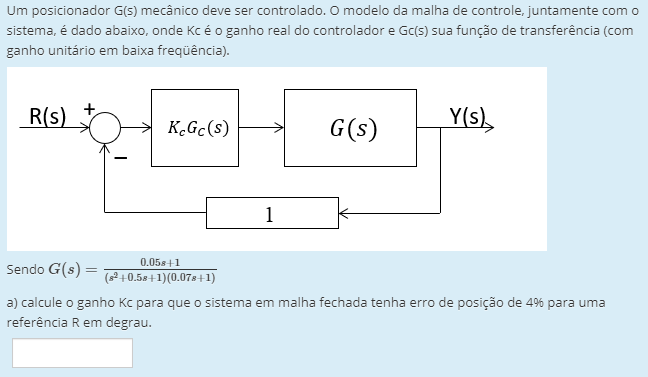

Erro ao degrau


$$K_p=\lim_{s\rightarrow0}K_cG_c(s)G(s)=K_c$$



$$e(\infty)=\frac{1}{1+K_p}=0.04$$


clear; clc; close all;
s=tf('s');
G=(0.05*s+1)/(s^2+0.5*s+1)/(0.07*s+1)

G =
 
             0.05 s + 1
  ---------------------------------
  0.07 s^3 + 1.035 s^2 + 0.57 s + 1
 
Continuous-time transfer function.



Kc=(1-0.04)/0.04

Kc = 24

[MG,MF]=margin(Kc*G)

MG = 1.1878

MF = 0.8606

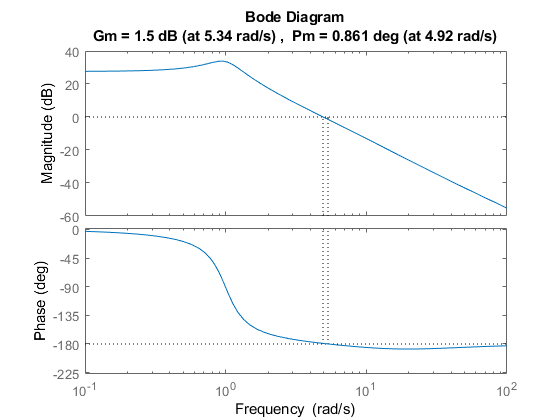

margin(Kc*G)

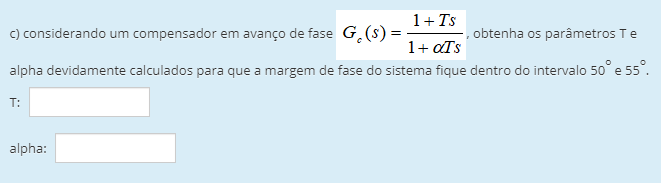

phi=50-MF+10

phi = 59.1394

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.0762

[mag,phase,wout] = bode(Kc*G);
modulo=-20*log10(1/sqrt(alfa))

modulo = -11.1814

wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 9.0544

T=1/(sqrt(alfa)*wc)

T = 0.4001

Gc=Kc*(1+T*s)/(1+T*s*alfa)

Gc =
 
  9.603 s + 24
  -------------
  0.03048 s + 1
 
Continuous-time transfer function.



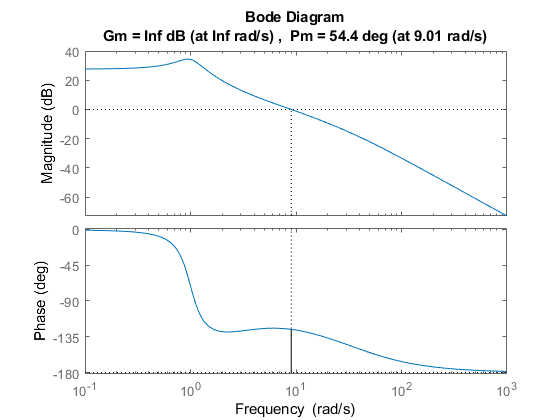

margin(G*Gc)

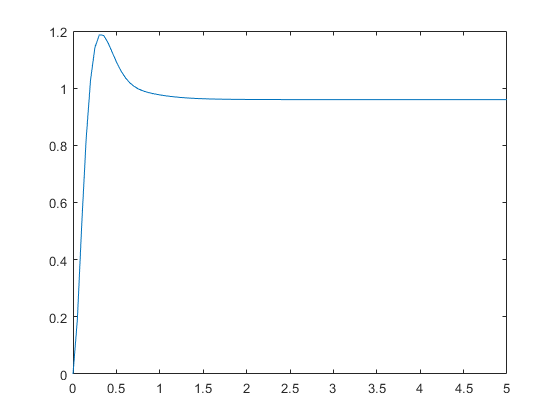

sys=feedback(G*Gc,1);
t=linspace(0,5,100);
y=step(sys,t);
plot(t,y)

erro=1-y(end);
fprintf('erro de %2.2f %%',erro*100)

erro de 4.00 %

## Questão 2

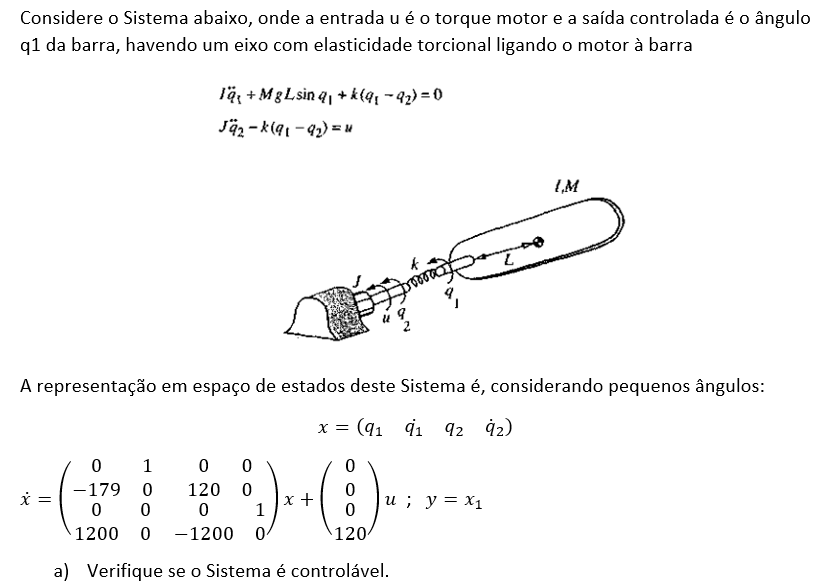

clear; clc; close all;
A=[0,1,0,0;-179,0,120,0;0,0,0,1;1200,0,-1200,0];
B=[0;0;0;120];
n=length(A)

n = 4

Mc=ctrb(A,B)

Mc =            0           0           0       14400
           0           0       14400           0
           0         120           0     -144000
         120           0     -144000           0


rank(Mc)

ans = 4

Sim, pois o rank da matriz de controlabilidade é igual ao número de variáveis de estado (ordem) do sistema.

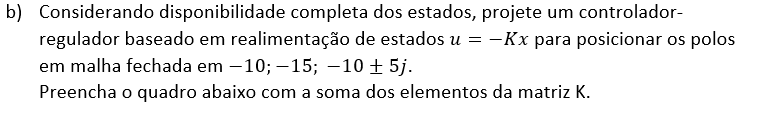

C=[1,0,0,0]; % a saída é q1
D=0; % não tem influência direta da entrada na saída
pk=[-10;-15;-10+5*j;-10-5*j]; % polos desejados
K=place(A,B,pk)

K =     3.8935   -0.1340   -5.0333    0.3750


soma=sum(K)

soma = -0.8989

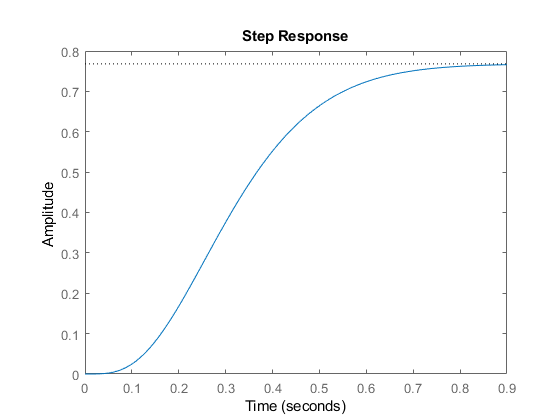

Kr=1;
Amf=A-B*K;
Bmf=B*Kr;
Cmf=C-D*K;
Dmf=D*Kr;
sys_mf=ss(Amf,Bmf,Cmf,Dmf);
step(sys_mf)

damp(sys_mf)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+01                 1.00e+00       1.00e+01         1.00e-01    
 -1.00e+01 + 5.00e+00i     8.94e-01       1.12e+01         1.00e-01    
 -1.00e+01 - 5.00e+00i     8.94e-01       1.12e+01         1.00e-01    
 -1.50e+01                 1.00e+00       1.50e+01         6.67e-02    


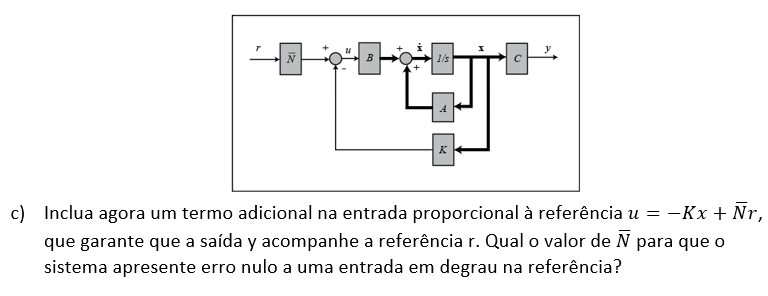

Kr=1/dcgain(sys_mf)

Kr = 1.3021

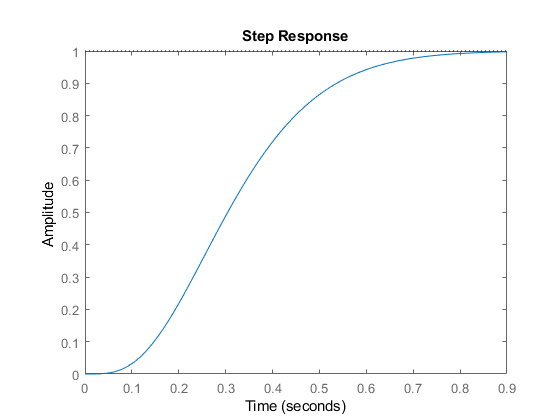

Amf=A-B*K;
Bmf=B*Kr;
Cmf=C-D*K;
Dmf=D*Kr;
sys_mf=ss(Amf,Bmf,Cmf,Dmf);
step(sys_mf)

damp(sys_mf)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+01                 1.00e+00       1.00e+01         1.00e-01    
 -1.00e+01 + 5.00e+00i     8.94e-01       1.12e+01         1.00e-01    
 -1.00e+01 - 5.00e+00i     8.94e-01       1.12e+01         1.00e-01    
 -1.50e+01                 1.00e+00       1.50e+01         6.67e-02    


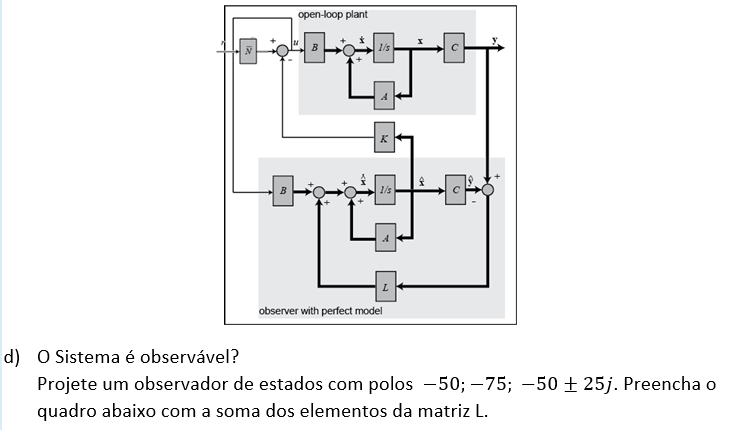

Mo=obsv(A,C)

Mo =      1     0     0     0
     0     1     0     0
  -179     0   120     0
     0  -179     0   120


rank(Mo)

ans = 4

Sim, pois o rank da matriz de observabilidade é igual ao número de variáveis de estado (ordem) do sistema.

p_obs=[-50;-75;-50+25*j;-50-25*j];
L=place(A',C',p_obs)'

L = 	1.0e+04 *

    0.0225
    1.7996
    0.4130
   -8.2894


format shortG
somaL=sum(L)

somaL =        -60543


format short

## Questão 3

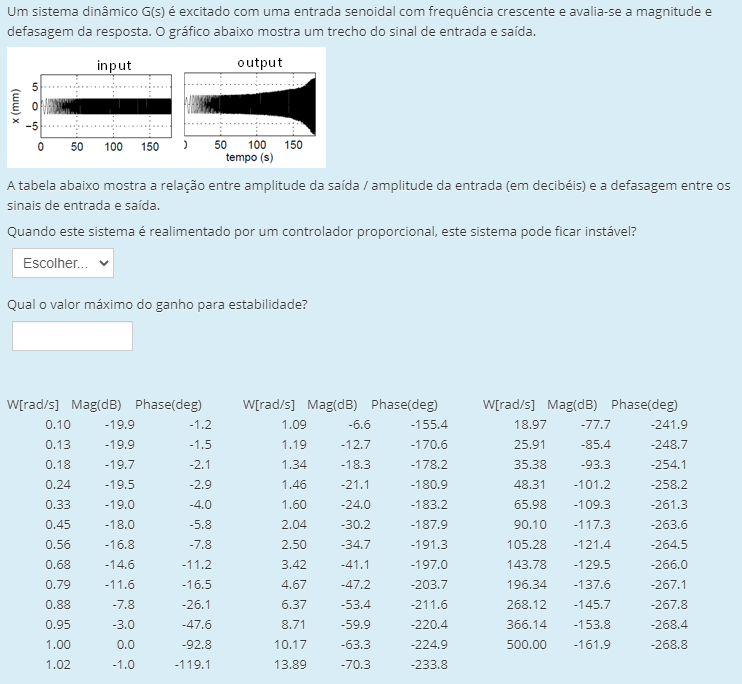

Sim, pois a margem de ganho não é infinita.

clear; clc; close all;
MG=21.1 %dB, ganho na frequeência em que a fase é -180º

MG =          21.1


O ganho máximo a partir do qual o sistema é instável é aquele que zera a margem de ganho.

Kmax=10^(MG/20)

Kmax =         11.35
